# Sample 4-1

## 線形シフト不変システム

単変量畳み込み

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Linear shift-invariant systems

Univariate convolution

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

### 入力信号 $\{u[n]\}_n
$ 

(Input signal $\{u[n]\}_n
$)

% Input x[n]
u = [1 2 3];

### 線形シフト不変システムのインパルス応答 $\{h[n]\}_n
$ 

(Impulse response of a linear shift-invariant system $\{h[n]\}_n
$)

% Impulse response h[n]
h = [1 1 1]/3;

### 線形シフト不変システムの出力応答$\{v[n]\}_n
$ 

(The linear shift-invariant system response $\{v[n]\}_n
$)

畳み込み演算 (Convolution)

        
$$\{v[n]\}_n=\{h[n]\}_n \ast \{u[n]\}_n = \sum_{k=-\infty}^{\infty}u[k]\{h[n-k]\}_n
$$


% Output y[n]
v = conv(h,u);

### 入出力のプロット

(Plot of the input and output)

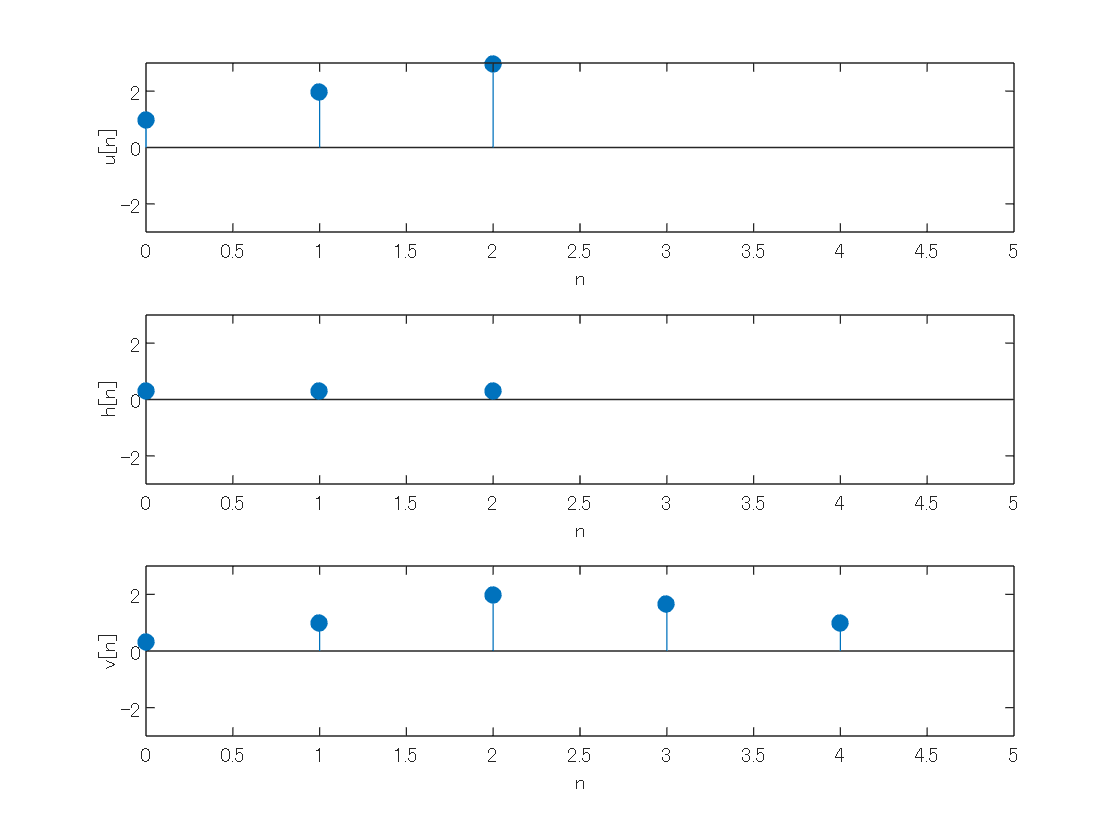

% Lengths of u, h and v
nu = length(u);
nh = length(h);
nv = length(v);

figure(1)
amax = max(max(abs(u)),max(abs(v)));
%% u[n]
subplot(3,1,1)
stem(0:nu-1,u,'filled')
axis([0 nv -amax amax])
xlabel('n')
ylabel('u[n]')

%% h[n]
subplot(3,1,2)
stem(0:nh-1,h,'filled')
axis([0 nv -amax amax])
xlabel('n')
ylabel('h[n]')

%% v[n]
subplot(3,1,3)
stem(0:nv-1,v,'filled')
axis([0 nv -amax amax])
xlabel('n')
ylabel('v[n]')

### 重み付けインパルス信号への分解と重み付けインパルス応答の合成

(Decomposition into weighted impulse signals and synthesis of weighted impulse responses)

        
$$\{v[n]\}_n = \sum_{k=-\infty}^{\infty} \{v_k[n]\}_n,$$


        
$$\{u[n]\}_n = \sum_{k=-\infty}^{\infty} \{u_k[n]\}_n,$$


ただし、(where)

        
$$\{v_k[n]\}_n = \{h[n]\}_n \ast \{u_k[n]\}_n,
$$


        
$$\{u_k[n]\}_n = u[k]\{\delta[n-k]\}_n.$$


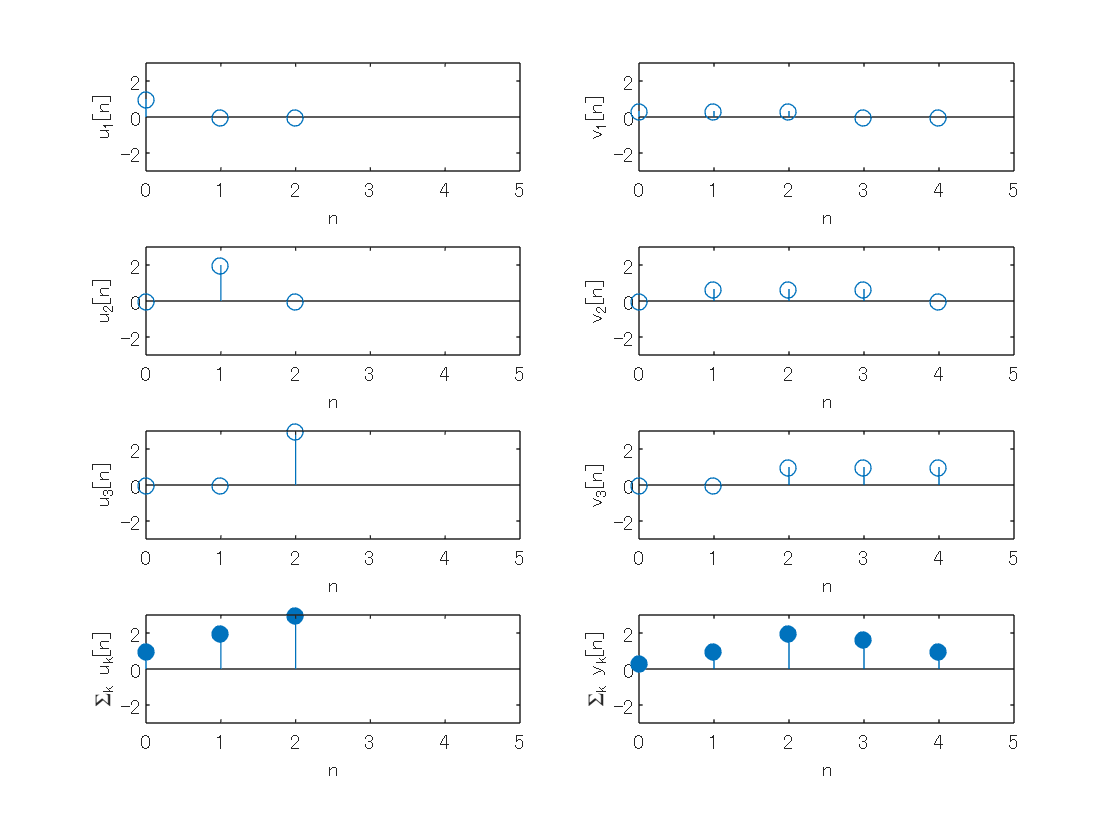

figure(2)
uu = 0;
vv = 0;
for k = 1:nu
    % Shifted impluse signal \delta[n-k]
    ds = zeros(size(u),'like',u);
    ds(k) = 1;
    % Weighted impulse signal uk[n] = u[k]\delta[n-k]
    uk = u(k)*ds;
    % System response to shifted impulse signal and weighting 
    % vk[n] = h[n] * uk[n]
    vk = u(k)*conv(h,ds);
    % Plot uk[n]
    subplot(nu+1,2,2*k-1)
    stem(0:nu-1,uk)
    axis([0 nv -amax amax])
    xlabel('n')
    ylabel(sprintf('u_%d[n]',k))
    % Plot vk[n]
    subplot(nu+1,2,2*k)
    stem(0:nv-1,vk)
    axis([0 nv -amax amax])
    xlabel('n')
    ylabel(sprintf('v_%d[n]',k))
    % Accumurate uk[n] and vk[n]
    uu = uu + uk;
    vv = vv + vk;
end
% Plot accumulation of uk[n]
subplot(nu+1,2,2*(nu+1)-1)
stem(0:nu-1,uu,'filled')
axis([0 nv -amax amax])
xlabel('n')
ylabel('\Sigma_k u_k[n]')
% Plot accumulation of vk[n]
subplot(nu+1,2,2*(nu+1))
stem(0:nv-1,vv,'filled')
axis([0 nv -amax amax])
xlabel('n')
ylabel('\Sigma_k y_k[n]')

### 平均自乗誤差(MSE)による評価

(Evaluation in terms of the mean squared errors (MSE))

        
$$\mathrm{MSE}(\{x[n]\}_n,\{y[n]\}_n) \colon =\frac{1}{\left|\Omega\right|}\sum_{n\in\Omega}\left|x[n]-y[n]\right|^2,$$


ただし， $\Omega$は添え字集合， $|\Omega|$ は添え字の数．(where $\Omega$ denotes the index set and $|\Omega|$ means the cardinality.)

% Evaluation of uu
mymse = @(x,y) mean((double(x)-double(y)).^2,'all');
mymse(u,uu)

ans = 0

% Evaluation of vv
mymse(v,vv)

ans = 9.8608e-33

© Copyright, Shogo MURAMATSU, All rights reserved.